# RVC2: Chapter 5

close all
clear all
clc

## 5.1.1.  Braitenberg vehices

sl_braitenberg
sim('sl_braitenberg');

## 5.1.2  Simple automata

load house
about house
place

bug = Bug2(house);
bug.plot();
bug.query(place.br3, place.kitchen, 'animate');

p = bug.query(place.br3, place.kitchen)
about(p)
%p = bug.query([], place.kitchen);  % this requires the user to prompt for a start location


## Sidebar: Making a map (page 131)

map = zeros(100, 100);
map(40:50,20:80) = 1;
%map = makemap(100)  % this requires user input

## 5.2.1  Distance transform

dx = DXform(house);
dx.plan(place.kitchen)

dx.plot()

dx.query(place.br3, 'animate');

p = dx.query(place.br3);

dx.plot(p)

numrows(p)

dx.plan(place.kitchen, 'animate');

dx.plot3d(p)

and now we inflate the obstacles

dx = DXform(house, 'inflate', 5);
dx.plan(place.kitchen)
p = dx.query(place.br3);
dx.plot(p)

dx.plot(p, 'inflated')

## Sidebar: Navigation class (page 132)

This code is by way of example and won't actually run.  You'd need to define world, start, goal and use a concrete subclass of Navigation instead of MyNavClass (eg. DXform or PRM)

% nav = MyNavClass(world)
% nav.plan()
% nav.plan(goal)
% 
% p = nav.query(start, goal)
% p = nav.query(start)
% nav.plot()
% nav.plot(p)

## 5.2.2  D*

ds = Dstar(house);
c = ds.costmap();
ds.plan(place.kitchen);
ds.niter
ds.query(place.br3);

ds.modify_cost( [300,325; 115,125], 5 );

ds.plan();
ds.niter
ds.query(place.br3);

## 5.2.3  Introduction to roadmap methods

free = 1 - house;
free(1,:) = 0; free(100,:) = 0;
free(:,1) = 0; free(:,100) = 0;
skeleton = ithin(free);

## 5.2.4 PRM

prm = PRM(house)
randinit
prm.plan('npoints', 150)
prm
prm.plot()

p = prm.query(place.br3, place.kitchen);
about p

## Sidebar: Voronoi tessellation (page 137)

sites = rand(10, 2);
voronoi(sites(:,1), sites(:,2))

## Sidebar: random numbers (page 139)

rand
rand
rand
randinit
rand
rand

## 5.2.4 Lattice planner

lp = Lattice();
lp.plan('iterations', 2)

13 nodes created


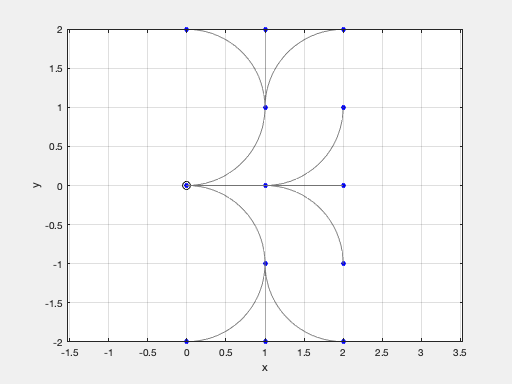

lp.plot()


lp.plan('iterations', 8)

780 nodes created


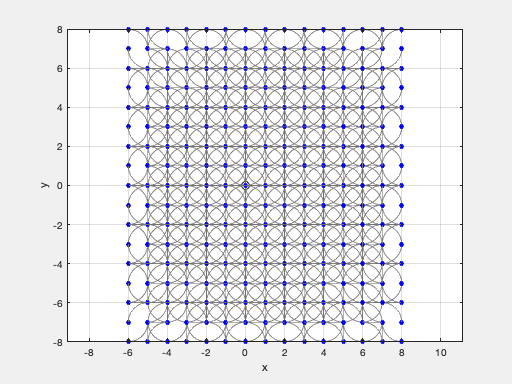

lp.plot()


lp.query( [1 2 pi/2], [2 -2 0] );

A* path cost 6


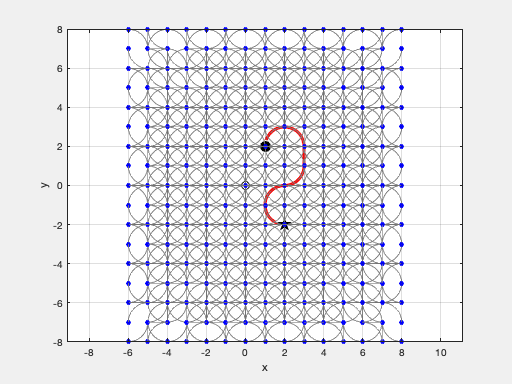


lp.plot()


p = lp.query( [1 2 pi/2], [2 -2 0] )

A* path cost 6


p =     1.0000    2.0000    1.5708
    2.0000    3.0000         0
    3.0000    2.0000   -1.5708
    3.0000    1.0000   -1.5708
    2.0000    0.0000   -3.1416
    1.0000   -1.0000   -1.5708
    2.0000   -2.0000         0


about p

p [double] : 7x3 (168 bytes)



lp.plan('cost', [1 10 10])

780 nodes created


lp.query( [1 2 pi/2], [2 -2 0] );

A* path cost 35


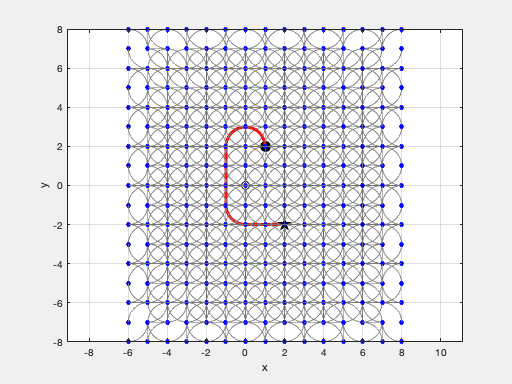

lp.plot()


load road
lp = Lattice(road, 'grid', 5, 'root', [50 50 0])
lp.plan();
lp.query([30 45 0], [50 20 0])
lp.plot()

## 5.2.5 Rapidly exploring random trees (RRT)

car = Bicycle('steermax', 0.5);
rrt = RRT(car, 'npoints', 1000)

rrt.plan();
rrt.plot();

rrt = RRT(car, road, 'npoints', 1000, 'root', [50 22 0],'simtime', 4)
rrt.plan();

p = rrt.query([40 45 0], [50 22 0]);

about p

rrt.plot(p)

plot_vehicle(p, 'box', 'size', [20 30], 'fill', 'r', 'alpha', 0.1)


bdclose('all')